# Taxi Deployment 

## Data Extraction and Introduction 

To get started, navigate to the Taxi Project folder, and run the script **generateTaxiPickupTable.mlx**. 

*Note it may take a while to finish. *

This will create (and save) two tables: `pickupLocations` and `taxiPickups. `A preview and description of each table is given below. 

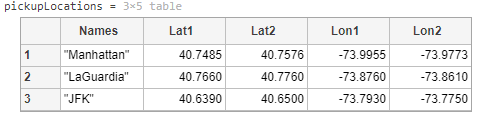

The table `pickupLocations` gives the latitude and logitude bounds for three pickup zones: 

- **Manhattan**: here meaning an area of high taxi traffic surrounding Penn Station, Grand Central Station, and the Port Authority Bus Terminal

- **LaGuardia**: meaning an area surrounding LaGuardia airport

- **JFK**: similarly meaning an area surrounding JFK airport. 

The zones are shown below for reference. 

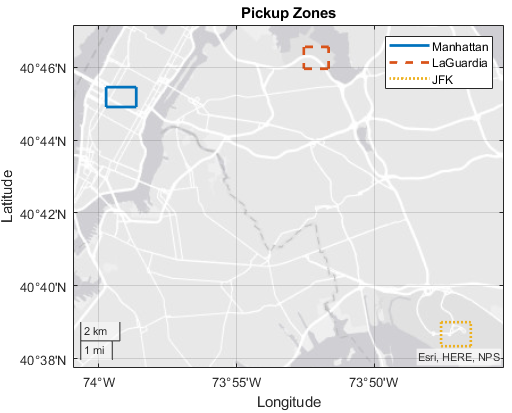

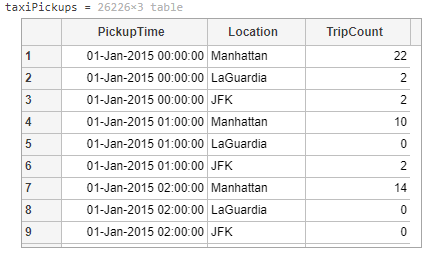

The table `taxiPickpus` represents the number of pickups in your data over one hour intervals of 2015 in the zones defined in `pickupLocations`. The start of each hour is specified in the `PickupTime` datetime variable, the zone is specified by the `Location` categorical variable, and the number of pickups is given by the `TripCount`. 

## Data Exploration and Partitioning 

The script **generateTaxiPickupTable.mlx **in the previous section saved copies of the tables to a MAT file named **taxiPickupData.mat**. To avoid having to run the script again if you continue working after clearing your workspace, the code below loads the saved data. 

% Make sure to follow the instructions in the previous section
if ~isempty(which('-all','pickupLocations.mat'))
    load pickupLocations.mat 
else
    error("The file taxiPickupData.mat is not found on the MATLAB path. Add it to the path or run generateTaxiPickupTable.mlx to generate it.")
end
if ~isempty(which('-all','taxiPickups.mat'))
    load taxiPickups.mat 
else
    error("The file taxiPickupData.mat is not found on the MATLAB path. Add it to the path or run generateTaxiPickupTable.mlx to generate it.")
end

### Visualization and Analysis

Large number of LaGuardia trips = 0!

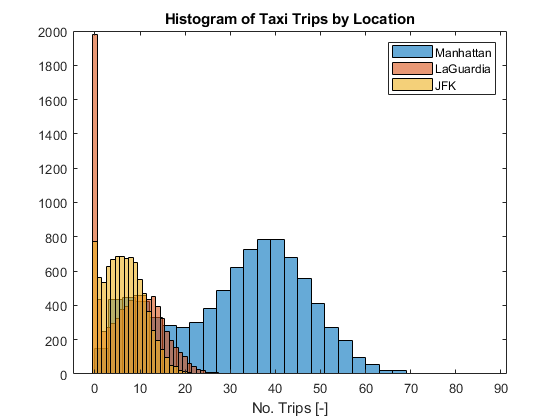

histogram(taxiPickups.TripCount(taxiPickups.Location == "Manhattan"))
hold on
histogram(taxiPickups.TripCount(taxiPickups.Location == "LaGuardia"))
histogram(taxiPickups.TripCount(taxiPickups.Location == "JFK"))
title("Histogram of Taxi Trips by Location")
xlabel("No. Trips [-]")
legend(["Manhattan", "LaGuardia", "JFK"],"Location","northeast")
hold off

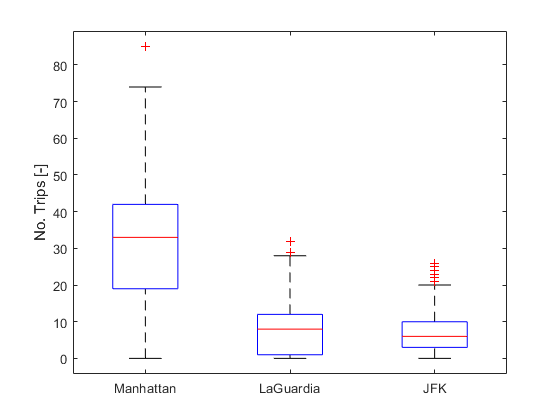

boxplot(taxiPickups.TripCount,taxiPickups.Location)
ylabel("No. Trips [-]")

### Separate Test Data 

Set the random number generator seed to 10 for repeatability. Setting aside 20% of the data for model testing:

rng(10);
taxiPart = cvpartition(height(taxiPickups),"Holdout",0.2);

taxiPickupsTrain = taxiPickups(training(taxiPart),:);
taxiPickupsTest = taxiPickups(test(taxiPart),:);

## Models Training and Validation 

### Preprocessing 

Adding in the following features:

- `TimeOfDay` (numerical)

- `DayOfWeek` (categorical)

- `DayOfMonth` (numerical)

- `DayOfYear` (numerical) 

taxiPickupsTrain = providedPreprocessing(taxiPickupsTrain);

### Model Training

Using a bagged tree model optimized via the regression learner app:

[taxiTree, validationRMSE] = trainRegressionModel(taxiPickupsTrain)

I used a **20% holdout validation** rather than k-fold cross validation due to the size of the data set.  Also, with a low ratio of predictors to observations, it is unlikely the model will be over-trained.  The **Validaion RMSE is 4.6**, pretty good!

## Model Testing and Evaluation 

### Testing

Preprocess the test data as needed, and use it to test your best model. Provide your code and report at least the $RMSE$ and $R^2$. You will need to achieve a test $RMSE$ at or below $4.9$ to receive full points here. 

taxiPickupsTest = providedPreprocessing(taxiPickupsTest);
PickupsPredTest = taxiTree.predictFcn(taxiPickupsTest);
PickupsPredTrain = taxiTree.predictFcn(taxiPickupsTrain);
RMSE = sqrt(mean((PickupsPredTest - taxiPickupsTest.TripCount).^2))

RMSE = 4.5882

SST = sum((taxiPickupsTest.TripCount-mean(taxiPickupsTest.TripCount)).^2);
SSE = sum((taxiPickupsTest.TripCount-PickupsPredTest).^2);
Rsq = (SST-SSE)/SST

Rsq = 0.9061

### Evaluation

The model predicts new trip counts quite well.  The **RMSE for the test set is very close to that of the training set** which is a good indication that the model is not over-trained.

The residuals density plot shows an under-prediction of trip counts when the number of trips is very high.  This is preferred because Mr. Walker would lose money by sending too many taxis to an area where many of them would not get trips.

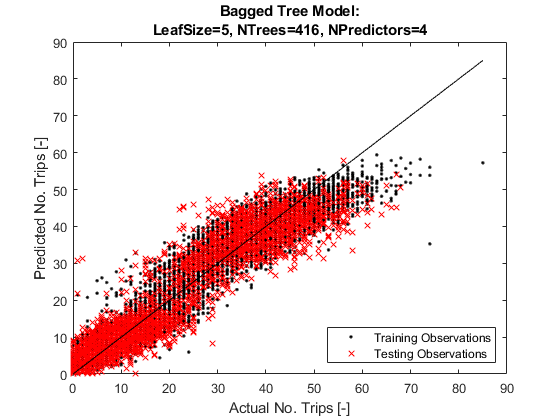

plot(taxiPickupsTrain.TripCount,PickupsPredTrain,'k.');
hold on
plot(taxiPickupsTest.TripCount,PickupsPredTest,'rx');
plot(taxiPickupsTrain.TripCount,taxiPickupsTrain.TripCount,'k-');
xlabel("Actual No. Trips [-]")
ylabel("Predicted No. Trips [-]")
title(["Bagged Tree Model:";"LeafSize=5, NTrees=416, NPredictors=4"])
legend(["Training Observations","Testing Observations"],"Location","southeast")
hold off

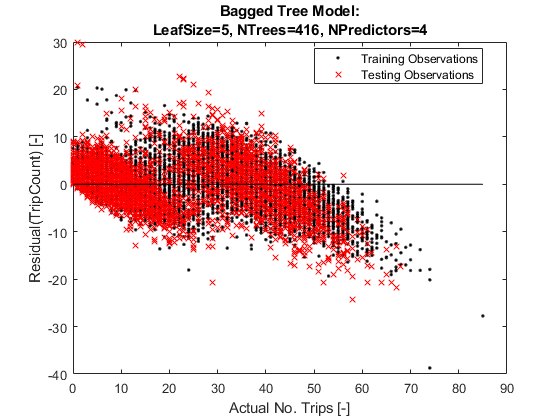


ResidTrain = PickupsPredTrain - taxiPickupsTrain.TripCount;
ResidTest = PickupsPredTest - taxiPickupsTest.TripCount;
plot(taxiPickupsTrain.TripCount,ResidTrain,'k.')
hold on
plot(taxiPickupsTest.TripCount,ResidTest,'rx')
plot(taxiPickupsTrain.TripCount,0*taxiPickupsTrain.TripCount,'k-')
ylabel("Residual(TripCount) [-]")
xlabel("Actual No. Trips [-]")
title(["Bagged Tree Model:";"LeafSize=5, NTrees=416, NPredictors=4"])
legend(["Training Observations","Testing Observations"],"Location","best")
hold off

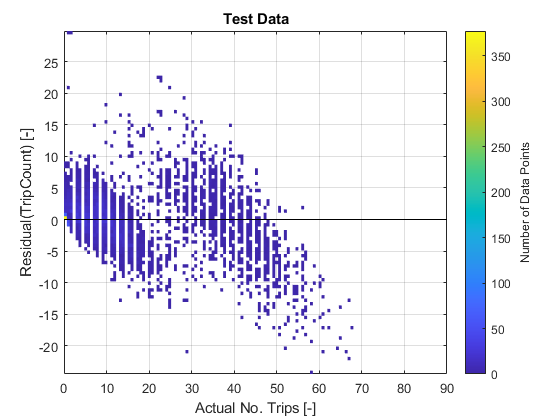


histogram2(taxiPickupsTest.TripCount,ResidTest,100,"DisplayStyle","tile")
hold on
line([0 90],[0 0],"Color","k")
title("Test Data")
ylabel("Residual(TripCount) [-]")
xlabel("Actual No. Trips [-]")
cb = colorbar();
cb.Label.String = "Number of Data Points";
hold off

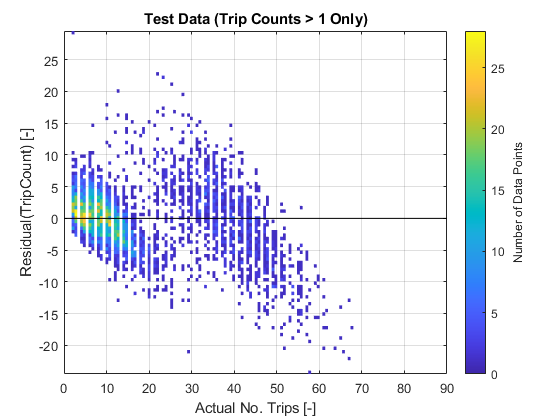


histogram2(taxiPickupsTest.TripCount(taxiPickupsTest.TripCount > 1),ResidTest(taxiPickupsTest.TripCount > 1),100,"DisplayStyle","tile")
hold on
line([0 90],[0 0],"Color","k")
title("Test Data (Trip Counts > 1 Only)")
ylabel("Residual(TripCount) [-]")
xlabel("Actual No. Trips [-]")
cb = colorbar();
cb.Label.String = "Number of Data Points";
hold off

## Model Application, Results, and Analysis

### Apply Model 

Apply model for future predictions next year.  Load data and select a day:

taxiPickups2016 = table; 
taxiPickups2016.PickupTime = taxiPickups.PickupTime + years(1); 
taxiPickups2016.Location = taxiPickups.Location;
taxiPickups2016 = providedPreprocessing(taxiPickups2016); 
% Display only the first 8 rows of the table
head(taxiPickups2016)

ans = 8×6 table
        PickupTime         Location     TimeOfDay    DayOfWeek    DayOfMonth    DayOfYear
    ___________________    _________    _________    _________    __________    _________

    2016-01-01 05:49:12    Manhattan      5.82        Friday          1             1    
    2016-01-01 05:49:12    LaGuardia      5.82        Friday          1             1    
    2016-01-01 05:49:12    JFK            5.82        Friday          1             1    
    2016-01-01 06:49:12    Manhattan      6.82        Friday          1             1    
    2016-01-01 06:49:12    LaGuardia      6.82        Friday          1             1    
    2016-01-01 06:49:12    JFK            6.82        Friday          1             1    
    2016-01-01 07:49:12    Manhattan      7.82        Frida

myDay = datetime("2016-5-5")

myDay = datetime
   05-May-2016


taxiPickupsMyDay = taxiPickups2016(day(taxiPickups2016.PickupTime,"dayofyear") == day(myDay,"dayofyear"),:);

Use the best model to predict `TripCount` on 5/5/2016: 

taxiPickupsMyDay.TripCount = taxiTree.predictFcn(taxiPickupsMyDay);


Again, to focus on machine learning, we have provided the necessary table manipulations and calculations below to use your model predictions to give the predicted fraction of trips happening in each hour on your selected day. 

Uncomment below once you have defined the table `taxiPickupsMyDay` above. 

taxiPickupsMyDayTotals = groupsummary(taxiPickupsMyDay,"PickupTime","sum","TripCount");
taxiPickupsMyDay = join(taxiPickupsMyDay,taxiPickupsMyDayTotals,"RightVariables","sum_TripCount");
taxiPickupsMyDay.PickupFraction = taxiPickupsMyDay.TripCount./taxiPickupsMyDay.sum_TripCount;
taxiPickupsMyDayFractions = unstack(taxiPickupsMyDay,"PickupFraction","Location","GroupingVariables","PickupTime");

### Use the Results to Allocate Fleet

In general, the **majority of the fleet (71%) should be allocated to Manhattan**, particularly in the morning hours.  As the day progresses, more taxis should be allocated to the airports.

ManhattanPct = 100*mean(taxiPickupsMyDayFractions.Manhattan)

ManhattanPct = 71.3201

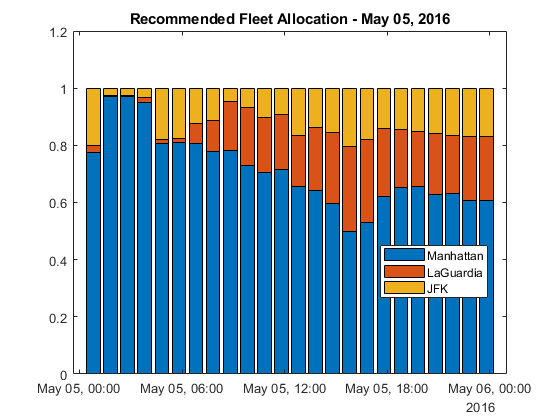

MyMat = table2array(taxiPickupsMyDayFractions(:,2:4));
bar(taxiPickupsMyDayFractions.PickupTime,MyMat,'stacked')
title("Recommended Fleet Allocation - May 05, 2016")
legend(["Manhattan","LaGuardia","JFK"],"Location","best")

function [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% Returns a trained regression model and its RMSE. This code recreates the
% model trained in Regression Learner app. Use the generated code to
% automate training the same model with new data, or to learn how to
% programmatically train models.
%
%  Input:
%      trainingData: A table containing the same predictor and response
%       columns as those imported into the app.
%
%  Output:
%      trainedModel: A struct containing the trained regression model. The
%       struct contains various fields with information about the trained
%       model.
%
%      trainedModel.predictFcn: A function to make predictions on new data.
%
%      validationRMSE: A double containing the RMSE. In the app, the
%       History list displays the RMSE for each model.
%
% Use the code to train the model with new data. To retrain your model,
% call the function from the command line with your original data or new
% data as the input argument trainingData.
%
% For example, to retrain a regression model trained with the original data
% set T, enter:
%   [trainedModel, validationRMSE] = trainRegressionModel(T)
%
% To make predictions with the returned 'trainedModel' on new data T2, use
%   yfit = trainedModel.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedModel.HowToPredict

% Auto-generated by MATLAB on 22-Sep-2020 05:49:55


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Location', 'TimeOfDay', 'DayOfWeek', 'DayOfMonth', 'DayOfYear'};
predictors = inputTable(:, predictorNames);
response = inputTable.TripCount;
isCategoricalPredictor = [true, false, true, false, false];

% Train a regression model
% This code specifies all the model options and trains the model.
template = templateTree(...
    'MinLeafSize', 5, ...
    'NumVariablesToSample', 4);
regressionEnsemble = fitrensemble(...
    predictors, ...
    response, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 416, ...
    'Learners', template);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
ensemblePredictFcn = @(x) predict(regressionEnsemble, x);
trainedModel.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedModel.RequiredVariables = {'DayOfMonth', 'DayOfWeek', 'DayOfYear', 'Location', 'TimeOfDay'};
trainedModel.RegressionEnsemble = regressionEnsemble;
trainedModel.About = 'This struct is a trained model exported from Regression Learner R2020a.';
trainedModel.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'Location', 'TimeOfDay', 'DayOfWeek', 'DayOfMonth', 'DayOfYear'};
predictors = inputTable(:, predictorNames);
response = inputTable.TripCount;
isCategoricalPredictor = [true, false, true, false, false];

% Set up holdout validation
cvp = cvpartition(size(response, 1), 'Holdout', 0.2);
trainingPredictors = predictors(cvp.training, :);
trainingResponse = response(cvp.training, :);
trainingIsCategoricalPredictor = isCategoricalPredictor;

% Train a regression model
% This code specifies all the model options and trains the model.
template = templateTree(...
    'MinLeafSize', 5, ...
    'NumVariablesToSample', 4);
regressionEnsemble = fitrensemble(...
    trainingPredictors, ...
    trainingResponse, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 416, ...
    'Learners', template);

% Create the result struct with predict function
ensemblePredictFcn = @(x) predict(regressionEnsemble, x);
validationPredictFcn = @(x) ensemblePredictFcn(x);

% Add additional fields to the result struct


% Compute validation predictions
validationPredictors = predictors(cvp.test, :);
validationResponse = response(cvp.test, :);
validationPredictions = validationPredictFcn(validationPredictors);

% Compute validation RMSE
isNotMissing = ~isnan(validationPredictions) & ~isnan(validationResponse);
validationRMSE = sqrt(nansum(( validationPredictions - validationResponse ).^2) / numel(validationResponse(isNotMissing) ));
end